# LAB 4

**Name: Muhammad Asad Imran Rafique**

**Student ID: 48065145**

**Task 1**

**a)**

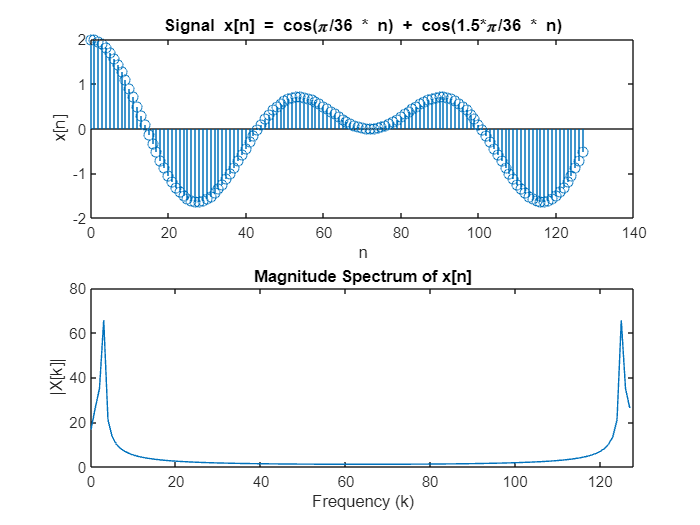

n = 0:127;
x = cos(pi/36 * n) + cos(1.5*pi/36 * n);

X = fft(x);
mag_X = abs(X);

figure;
subplot(2,1,1);
stem(n, x);
xlabel('n');
ylabel('x[n]');
title('Signal x[n] = cos(\pi/36 * n) + cos(1.5*\pi/36 * n)');


subplot(2,1,2);
plot((0:length(X)-1), mag_X);
xlabel('Frequency (k)');
ylabel('|X[k]|');
title('Magnitude Spectrum of x[n]');
xlim([0, 128]);

**b)**

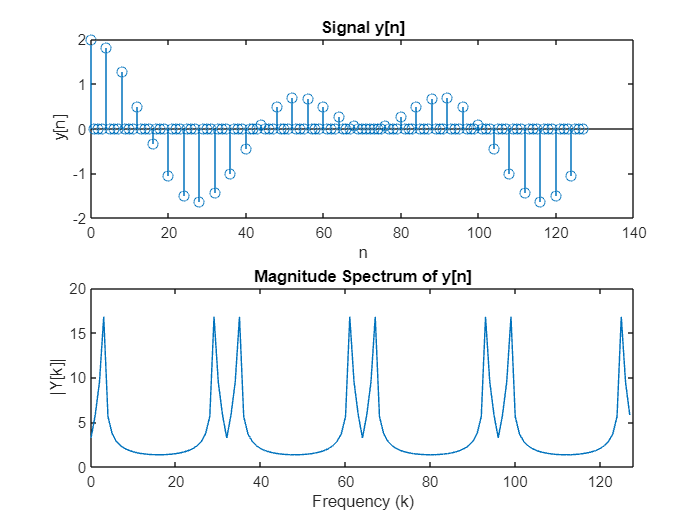

N = 128;
impulse_train = zeros(1, N);
impulse_train(1:4:end) = 1;
y = x .* impulse_train;

Y = fft(y);
mag_Y = abs(Y);

figure;
subplot(2,1,1);
stem(n, y);
xlabel('n');
ylabel('y[n]');
title('Signal y[n]');

subplot(2,1,2);
plot((0:length(Y)-1), mag_Y);
xlabel('Frequency (k)');
ylabel('|Y[k]|');
title('Magnitude Spectrum of y[n]');
xlim([0, N]);

**c)**

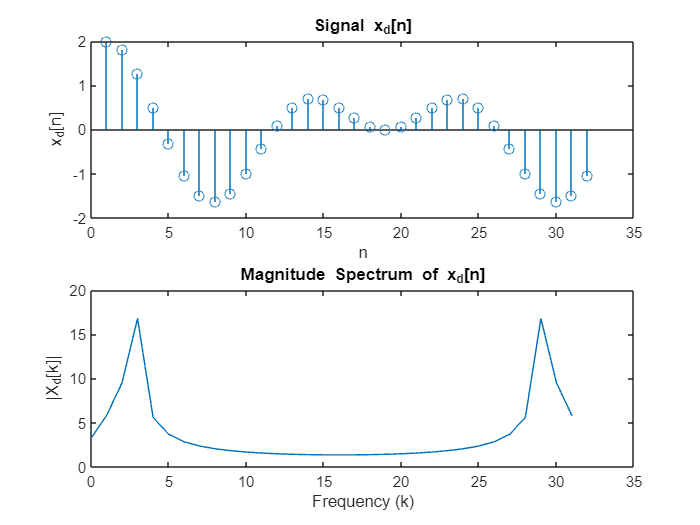

x_d = downsample(x,4);
X_d = fft(x_d);
mag_X_d = abs(X_d);

figure;
subplot(2,1,1);
stem(x_d);
xlabel('n');
ylabel('x_d[n]');
title('Signal x_d[n]');


subplot(2,1,2);
plot((0:length(X_d)-1), mag_X_d);
xlabel('Frequency (k)');
ylabel('|X_d[k]|');
title('Magnitude Spectrum of x_d[n]');

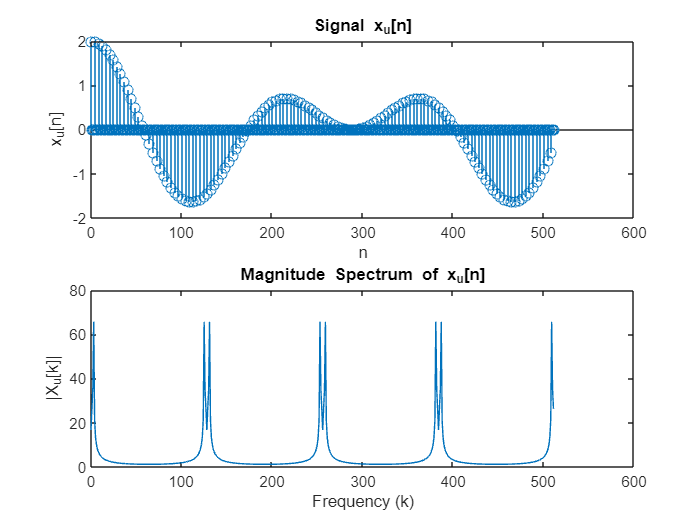


x_u = upsample(x,4);
X_u = fft(x_u);
mag_X_u = abs(X_u);

figure;
subplot(2,1,1);
stem(x_u);
xlabel('n');
ylabel('x_u[n]');
title('Signal x_u[n]');


subplot(2,1,2);
plot((0:length(X_u)-1), mag_X_u);
xlabel('Frequency (k)');
ylabel('|X_u[k]|');
title('Magnitude Spectrum of x_u[n]');

**Task 2**

**a)**

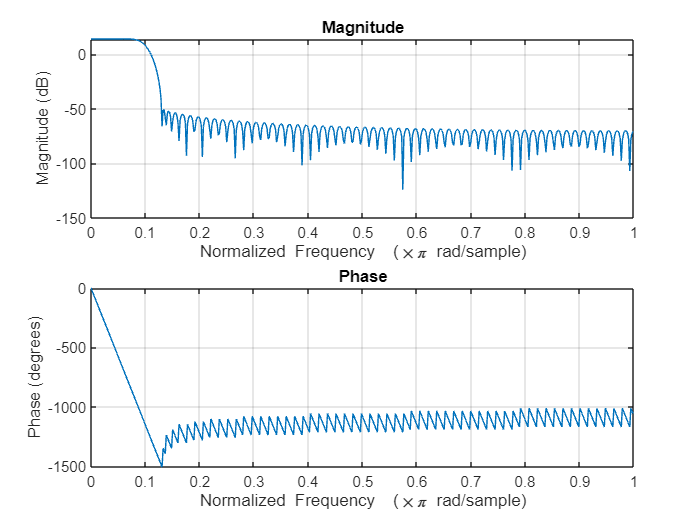

N = 128; 
beta = 6; 
fc = 300e3; 
gain = 5; 
window = kaiser(N+1, beta);
h = fir1(N, fc*2/(6e6), 'low', window);
h = h * gain;
figure;
freqz(h);

**b)**

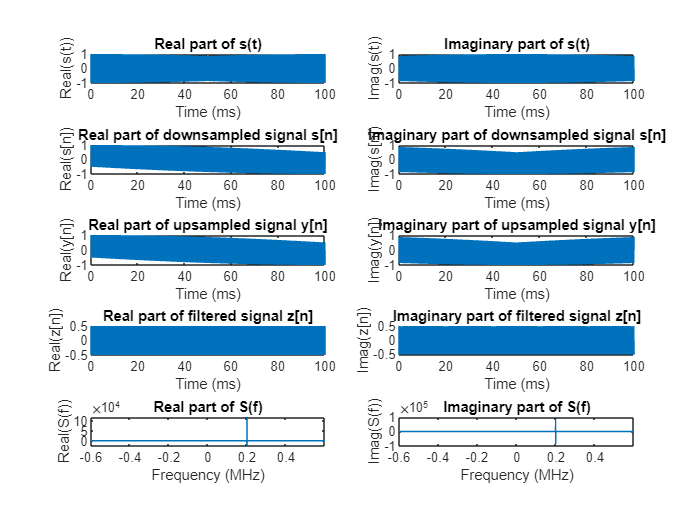

% Given parameters
A = 1; % Amplitude
theta = 0; % Phase
fc = 200e3; % Cutoff frequency in Hz

% Time vector
t = linspace(0, 0.1, 1.2e6*0.1); % Sampling frequency of 1.2 MHz for 0.1s

% Generate the continuous-time signal s(t)
s_t = A * exp(1j * (2*pi*fc*t + theta));

% Downsample s(t) by a factor of 2
s_n_downsampled = downsample(s_t, 2);

% Upsample s[n] by a factor of 10
s_n_upsampled = upsample(s_n_downsampled, 10);

% Filter the upsampled signal using the designed lowpass filter
z_n = filter(h, 1, s_n_upsampled);

% Plotting
figure;

% Plot time-domain sampled signals
subplot(5, 2, 1);
plot(t*1e3, real(s_t(1:length(t))));
xlabel('Time (ms)');
ylabel('Real(s(t))');
title('Real part of s(t)');

subplot(5, 2, 2);
plot(t*1e3, imag(s_t(1:length(t))));
xlabel('Time (ms)');
ylabel('Imag(s(t))');
title('Imaginary part of s(t)');

subplot(5, 2, 3);
plot(t(1:2:end)*1e3, real(s_n_downsampled));
xlabel('Time (ms)');
ylabel('Real(s[n])');
title('Real part of downsampled signal s[n]');

subplot(5, 2, 4);
plot(t(1:2:end)*1e3, imag(s_n_downsampled));
xlabel('Time (ms)');
ylabel('Imag(s[n])');
title('Imaginary part of downsampled signal s[n]');

% Correcting the time vector for y[n]
t_y = linspace(0, 0.1, length(s_n_upsampled));

subplot(5, 2, 5);
plot(t_y*1e3, real(s_n_upsampled));
xlabel('Time (ms)');
ylabel('Real(y[n])');
title('Real part of upsampled signal y[n]');

subplot(5, 2, 6);
plot(t_y*1e3, imag(s_n_upsampled));
xlabel('Time (ms)');
ylabel('Imag(y[n])');
title('Imaginary part of upsampled signal y[n]');

subplot(5, 2, 7);
plot(t_y*1e3, real(z_n));
xlabel('Time (ms)');
ylabel('Real(z[n])');
title('Real part of filtered signal z[n]');

subplot(5, 2, 8);
plot(t_y*1e3, imag(z_n));
xlabel('Time (ms)');
ylabel('Imag(z[n])');
title('Imaginary part of filtered signal z[n]');

% Compute and plot spectra
f_s = [1.2e6, 600e3, 6e6]; % Sampling frequencies for s[n], x[n], and y[n]

f = linspace(-0.5, 0.5, length(s_t)*10);
S_f = fftshift(fft(s_t, length(f)));

% Plot the real part of the spectrum of s(t)
subplot(5, 2, 9);
plot(f*f_s(1)/1e6, real(S_f));
xlabel('Frequency (MHz)');
ylabel('Real(S(f))');
title('Real part of S(f)');

% Plot the imaginary part of the spectrum of s(t)
subplot(5, 2, 10);
plot(f*f_s(1)/1e6, imag(S_f));
xlabel('Frequency (MHz)');
ylabel('Imag(S(f))');
title('Imaginary part of S(f)');

**c)**

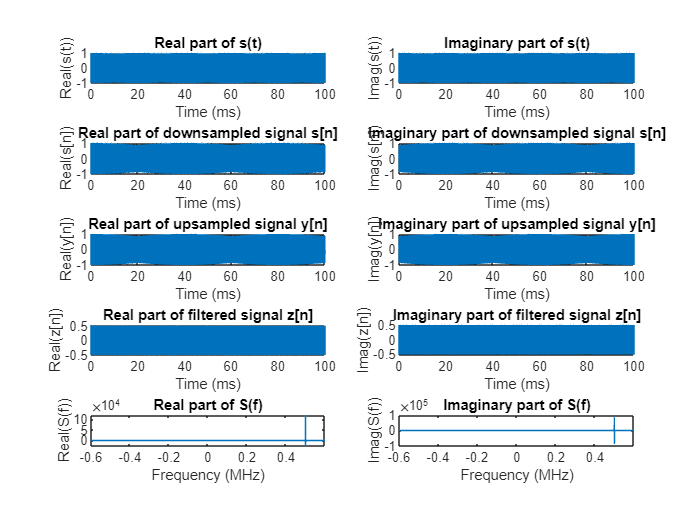

% Given parameters
A = 1; % Amplitude
theta = 0; % Phase
fc = 500e3; % Cutoff frequency in Hz

% Time vector
t = linspace(0, 0.1, 1.2e6*0.1); % Sampling frequency of 1.2 MHz for 0.1s

% Generate the continuous-time signal s(t)
s_t = A * exp(1j * (2*pi*fc*t + theta));

% Downsample s(t) by a factor of 2
s_n_downsampled = downsample(s_t, 2);

% Upsample s[n] by a factor of 10
s_n_upsampled = upsample(s_n_downsampled, 10);

% Filter the upsampled signal using the designed lowpass filter
z_n = filter(h, 1, s_n_upsampled);

% Plotting
figure;

% Plot time-domain sampled signals
subplot(5, 2, 1);
plot(t*1e3, real(s_t(1:length(t))));
xlabel('Time (ms)');
ylabel('Real(s(t))');
title('Real part of s(t)');

subplot(5, 2, 2);
plot(t*1e3, imag(s_t(1:length(t))));
xlabel('Time (ms)');
ylabel('Imag(s(t))');
title('Imaginary part of s(t)');

subplot(5, 2, 3);
plot(t(1:2:end)*1e3, real(s_n_downsampled));
xlabel('Time (ms)');
ylabel('Real(s[n])');
title('Real part of downsampled signal s[n]');

subplot(5, 2, 4);
plot(t(1:2:end)*1e3, imag(s_n_downsampled));
xlabel('Time (ms)');
ylabel('Imag(s[n])');
title('Imaginary part of downsampled signal s[n]');

% Correcting the time vector for y[n]
t_y = linspace(0, 0.1, length(s_n_upsampled));

subplot(5, 2, 5);
plot(t_y*1e3, real(s_n_upsampled));
xlabel('Time (ms)');
ylabel('Real(y[n])');
title('Real part of upsampled signal y[n]');

subplot(5, 2, 6);
plot(t_y*1e3, imag(s_n_upsampled));
xlabel('Time (ms)');
ylabel('Imag(y[n])');
title('Imaginary part of upsampled signal y[n]');

subplot(5, 2, 7);
plot(t_y*1e3, real(z_n));
xlabel('Time (ms)');
ylabel('Real(z[n])');
title('Real part of filtered signal z[n]');

subplot(5, 2, 8);
plot(t_y*1e3, imag(z_n));
xlabel('Time (ms)');
ylabel('Imag(z[n])');
title('Imaginary part of filtered signal z[n]');

% Compute and plot spectra
f_s = [1.2e6, 600e3, 6e6]; % Sampling frequencies for s[n], x[n], and y[n]

f = linspace(-0.5, 0.5, length(s_t)*10);
S_f = fftshift(fft(s_t, length(f)));

% Plot the real part of the spectrum of s(t)
subplot(5, 2, 9);
plot(f*f_s(1)/1e6, real(S_f));
xlabel('Frequency (MHz)');
ylabel('Real(S(f))');
title('Real part of S(f)');

% Plot the imaginary part of the spectrum of s(t)
subplot(5, 2, 10);
plot(f*f_s(1)/1e6, imag(S_f));
xlabel('Frequency (MHz)');
ylabel('Imag(S(f))');
title('Imaginary part of S(f)');

**Task 3**

**a)**

THE FIR FILTER REQUIRES 8150 COEFFICIENTS TO ACHIEVE THIS PERFORMANCE.

**b)**

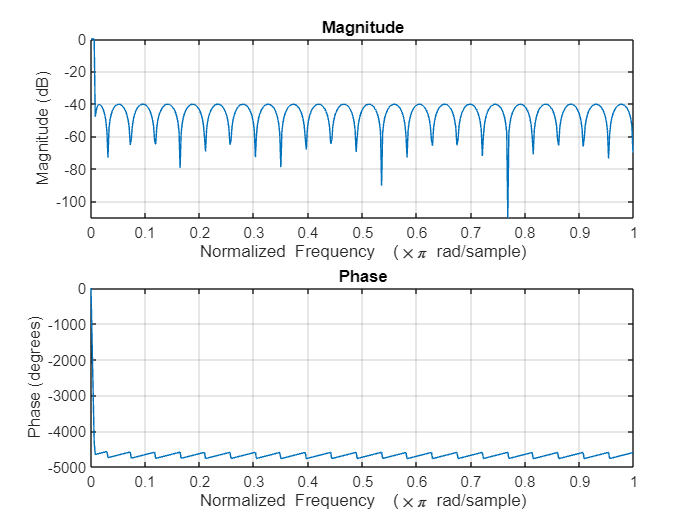

figure;
freqz(lpf_butter)

**c)**

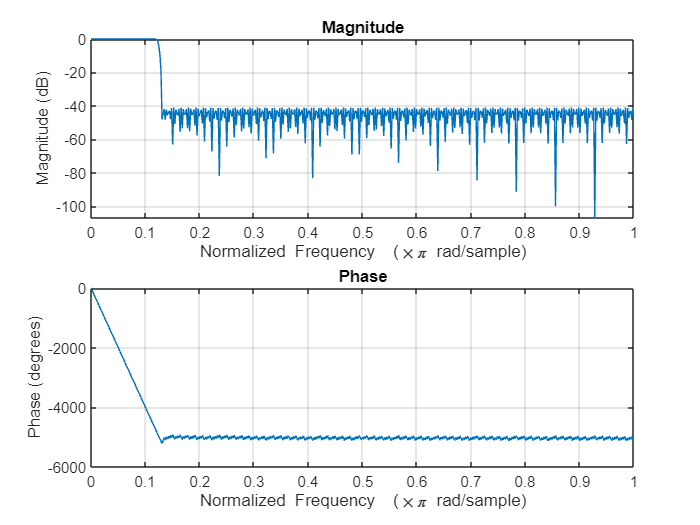

figure;
freqz(lpf_multistage_1);

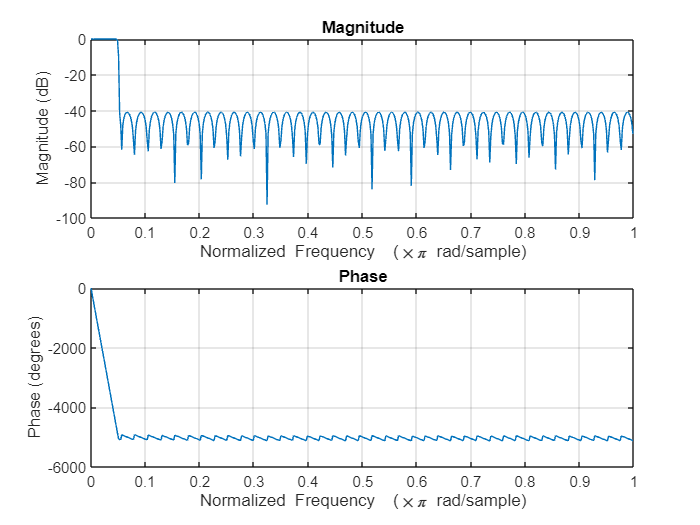

figure;
freqz(lpf_multistage_2);

BOTH FILTERS HAVE 1552 COEFFICIENTS IN TOTAL.